# Analyzing scRNASeq metabolic flux profiles

**Author:** Scott Campit

## Summary

This script analyzes the metabolic fluxes and growth rates from scCOBRA.

clear all

## 1. RECON1

### A. Load data

We'll load the latest data, which was simulated using MAGIC imputed scRNA-Seq data. Each cell is stored as an individual .mat file. We'll load up the fluxes and knockout growth rates as a matrix.

% Dell
datapath = dir(fullfile("D:/Analysis/EMT/recon1", "*.mat"));
load D:/Analysis/EMT/scRNASeq_recon1_diffexp.mat

Now let's instantiate several data objects we'll use to store the data.

% Create structure to save data into
flux = zeros(3744, length(datapath));
id = string();

Finally, let's load up everything.

for i = 1:size(datapath, 1)
    load(strcat(datapath(i).folder, '\', datapath(i).name));
    flux(:, i) = cobra_cell.flux;
    id(i) = cobra_cell.id;
end

Get reaction and gene IDs

rxn_ids = [model.rxns, model.rxnNames, model.subSystems];

### B. Save the data for UMAP embedding

Let's save the matrices now for data visualization.

filename = "D:/Analysis/EMT/recon1_cobra_results.xlsx";

#### Save Reaction fluxes

% Create column names
rxn_colnames = ["ID", "Name", "Subsystem", string(time_course)];

% Create matrix
tmpflx = [rxn_colnames; ...
          string(rxn_ids), string(flux)];

% Write to file
%writematrix(tmpflx, filename, 'Sheet', 'Flux')

### C. Construct identifiers by day 

We need to create identifiers by time. 

% Separate based on day
tmp_id = string(length(time_course));
for i = 1:length(time_course)
    try
        tmp = split(string(time_course{i}), ".");
        tmp_id(i) = tmp(1);
    catch ME
        tmp_id(i) = string(time_course{i});
    end
end

Also, we'll create indices to partition the data by time point. This loses information about the cells but we'll assume that mesenchymal cells are more prevalent in the later time points while epithelial cells are in the earlier time points.

% Indicies based on timepoints
idx0d = tmp_id == "0d";
idx8h = tmp_id == "8h";
idx1d = tmp_id == "1d";
idx3d = tmp_id == "3d";
idx7d = tmp_id == "7d";

Now let's also create a barplot of the distribution of cells.

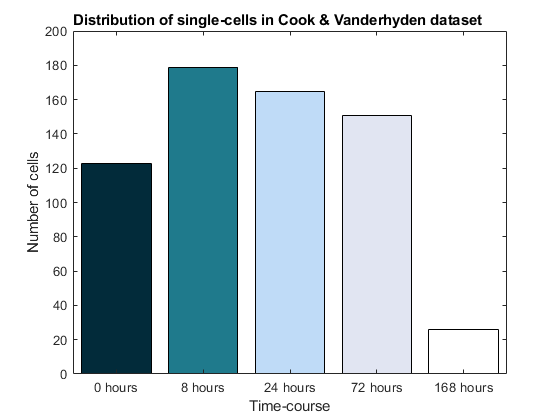

figure();
b1 = bar(categorical({'0 hours'}), sum(idx0d));
hold on;
b2 = bar(categorical({'8 hours'}), sum(idx8h));
hold on;
b3 = bar(categorical({'24 hours'}), sum(idx1d));
hold on;
b4 = bar(categorical({'72 hours'}), sum(idx3d));
hold on;
b5 = bar(categorical({'168 hours'}), sum(idx7d));
hold on;

set(b1, 'facecolor', "#022B3A");
set(b2, 'facecolor', "#1F7A8C");
set(b3, 'facecolor', "#BFDBF7");
set(b4, 'facecolor', "#E1E5F2");
set(b5, 'facecolor', "#FFFFFF");

ttl = title("Distribution of single-cells in Cook & Vanderhyden dataset");
ttl.Units = 'Normalize'; 
ttl.Position(1) = 0; 
ttl.HorizontalAlignment = 'left';  

xlabel("Time-course");
ylabel("Number of cells");
ylim([0, 200])
set(gca, 'FontName', 'Arial')

### D. Separate metabolic fluxes by day

First, remove identifiers and return to numerical

tmpflx = str2double(tmpflx(2:end, 4:end));

Now let's separate flux distributions by time point.

flux0d  = tmpflx(:, idx0d);
flux8h  = tmpflx(:, idx8h);
flux1d  = tmpflx(:, idx1d);
flux3d  = tmpflx(:, idx3d);
flux7d  = tmpflx(:, idx7d);

Now let's plot histograms

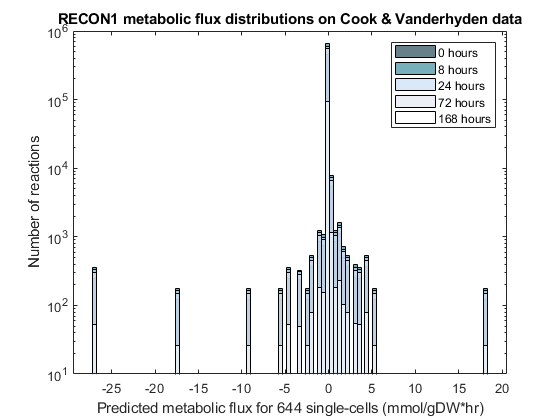

figure;
h1 = histogram(flux0d, 100);
hold on;
h2 = histogram(flux8h, 100);
hold on;
h3 = histogram(flux1d, 100);
hold on;
h4 = histogram(flux3d, 100);
hold on;
h5 = histogram(flux7d, 100);

set(h1, 'facecolor', "#022B3A");
set(h2, 'facecolor', "#1F7A8C");
set(h3, 'facecolor', "#BFDBF7");
set(h4, 'facecolor', "#E1E5F2");
set(h5, 'facecolor', "#FFFFFF");

legend("0 hours", ...
       "8 hours", ...
       "24 hours", ...
       "72 hours", ...
       "168 hours");
set(gca, 'YScale', 'log')
title("RECON1 metabolic flux distributions on Cook & Vanderhyden data");
xlabel("Predicted metabolic flux for 644 single-cells (mmol/gDW*hr)");
ylabel("Number of reactions");

### E. Metabolic flux fold change comparing day t over day 0

#### i. Get fold change across different time points

I added a value of 1 to not run into infinite values.

fc0008  = (abs(flux8h)+1)  ./ mean(abs(flux0d)+1, 2);
fc0024  = (abs(flux1d)+1)  ./ mean(abs(flux0d)+1, 2);
fc0072  = (abs(flux3d)+1)  ./ mean(abs(flux0d)+1, 2);
fc00168 = (abs(flux7d)+1)  ./ mean(abs(flux0d)+1, 2);

#### iii. Concatenate vertically

df = [fc0008, fc0024, fc0072, fc00168];

#### iv. Remove reactions that have no fold change in any reaction 

keep_idx   = all(df-1, 2);
df         = df(keep_idx, :);
rxn_ids    = rxn_ids(keep_idx, :);

#### v. Let's also apply the log2 operator on the data

log2df = log2(df);
df08   = log2df(:, 1:sum(idx8h));
df24   = log2df(:, (sum(idx8h)+1):(sum(idx1d)+sum(idx8h)));
df72   = log2df(:, (sum(idx1d)+sum(idx8h)+1):sum(idx3d)+sum(idx1d)+sum(idx8h), :);
df168  = log2df(:, (sum(idx3d)+sum(idx1d)+sum(idx8h)+1):sum(idx7d)+sum(idx3d)+sum(idx1d)+sum(idx8h));

#### vi. Let's plot a histogram of the data distribution

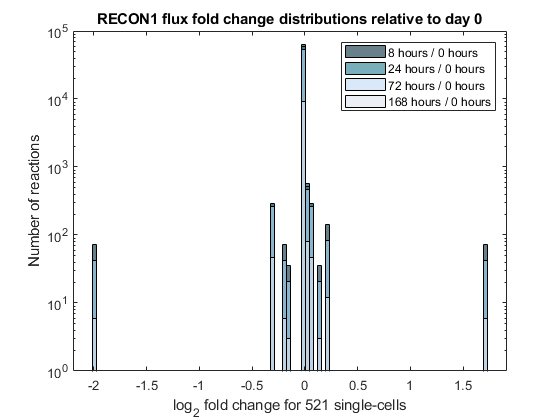

figure;
h1 = histogram(df08, 100);
hold on;
h2 = histogram(df24, 100);
hold on;
h3 = histogram(df72, 100);
hold on;
h4 = histogram(df168, 100);

set(h1, 'facecolor', "#022B3A");
set(h2, 'facecolor', "#1F7A8C");
set(h3, 'facecolor', "#BFDBF7");
set(h4, 'facecolor', "#E1E5F2");

legend("8 hours / 0 hours", ...
       "24 hours / 0 hours", ...
       "72 hours / 0 hours", ...
       "168 hours / 0 hours");
set(gca, 'YScale', 'log')
title("RECON1 flux fold change distributions relative to day 0");
xlabel("log_{2} fold change for 521 single-cells");
ylabel("Number of reactions");

#### vii. Compute average flux and standard deviation for single cells

**Average metabolic fluxes**

Create an average matrix for each time point

df08  = df(:, 1:sum(idx8h));
df24  = df(:, (sum(idx8h)+1):(sum(idx1d)+sum(idx8h)));
df72  = df(:, (sum(idx1d)+sum(idx8h)+1):sum(idx3d)+sum(idx1d)+sum(idx8h), :);
df168 = df(:, (sum(idx3d)+sum(idx1d)+sum(idx8h)+1):sum(idx7d)+sum(idx3d)+sum(idx1d)+sum(idx8h));

First, let's compute the average metabolic flux fold changes.

avg_df08  = mean(df08, 2);
avg_df24  = mean(df24, 2);
avg_df72  = mean(df72, 2);
avg_df168 = mean(df168, 2);

We'll make a single matrix and take the sume of averages across all time points.

% Construct a single matrix of the average metabolic flux fold changes
avg_df = [avg_df08, avg_df24, avg_df72, avg_df168];

% Get the sum of averages across all time points
avg_overall = sum(avg_df, 2)/4;

Let's plot a histogram of the data distribution.

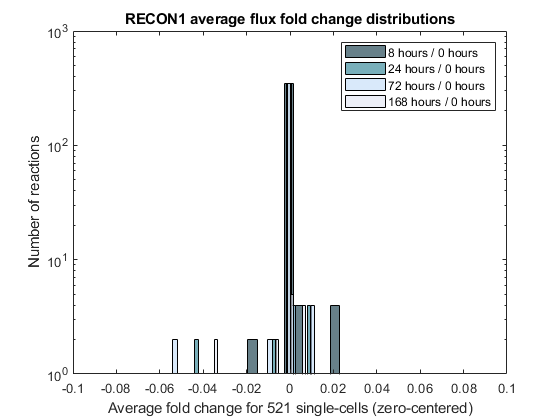

figure;
h1 = histogram(avg_df(:, 1)-1, 100);
hold on;
h2 = histogram(avg_df(:, 2)-1, 100);
hold on;
h3 = histogram(avg_df(:, 3)-1, 100);
hold on;
h4 = histogram(avg_df(:, 4)-1, 100);

set(h1, 'facecolor', "#022B3A");
set(h2, 'facecolor', "#1F7A8C");
set(h3, 'facecolor', "#BFDBF7");
set(h4, 'facecolor', "#E1E5F2");

legend("8 hours / 0 hours", ...
       "24 hours / 0 hours", ...
       "72 hours / 0 hours", ...
       "168 hours / 0 hours");
set(gca, 'YScale', 'log')
title("RECON1 average flux fold change distributions");
xlabel("Average fold change for 521 single-cells (zero-centered)");
ylabel("Number of reactions");
xlim([-0.1, 0.1])

**Standard deviation of metabolic fluxes**

% Compute variance of metabolic flux fold changes
var_df08  = var(df08, [], 2);
var_df24  = var(df24, [], 2);
var_df72  = var(df72, [], 2);
var_df168 = var(df168, [], 2);

We'll make a single matrix and take the sum of variances across all time points.

% Construct a single matrix of the variances
var_df = [var_df08, var_df24, var_df72, var_df168];

% Get the sum of variance across all time points
var_overall = sum(var_df, 2)/4;

Let's plot a histogram of the data distribution.

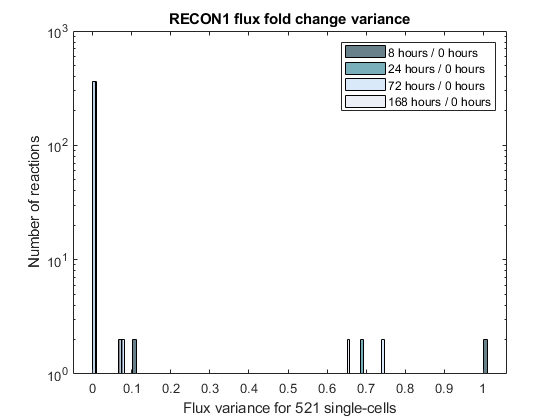

figure;
h1 = histogram(var_df(:, 1), 100);
hold on;
h2 = histogram(var_df(:, 2), 100);
hold on;
h3 = histogram(var_df(:, 3), 100);
hold on;
h4 = histogram(var_df(:, 4), 100);

set(h1, 'facecolor', "#022B3A");
set(h2, 'facecolor', "#1F7A8C");
set(h3, 'facecolor', "#BFDBF7");
set(h4, 'facecolor', "#E1E5F2");

legend("8 hours / 0 hours", ...
       "24 hours / 0 hours", ...
       "72 hours / 0 hours", ...
       "168 hours / 0 hours");
set(gca, 'YScale', 'log')
title("RECON1 flux fold change variance");
xlabel("Flux variance for 521 single-cells");
ylabel("Number of reactions");

**Sort the reactions by overall averages**

% Sort by descending
[~, idx] = sort(avg_overall, 'descend');
avg_ids = string(rxn_ids);
avg_ids = avg_ids(idx, :);

% Apply descend to matrix
final_df = avg_df(idx, :)-1;

**We need to make a string out of the data.**

tmp = [avg_df(:, 1)-1,  var_df(:, 1), ...
       avg_df(:, 2)-1,  var_df(:, 2), ...
       avg_df(:, 3)-1,  var_df(:, 3), ...
       avg_df(:, 4)-1,  var_df(:, 4), ...
       avg_overall-1, var_overall];
tmp = string(tmp);
tmp = tmp(idx, :);

**Now concatenate all of the data**

final_df = [avg_ids, tmp];
%final_df = final_df(idx, :);
final_df = ["ID", "Name", "Subsystem", ...
            "Mean(8/0)", "Var(8/0)", ...
            "Mean(24/0)", "Var(24/0)", ...
            "Mean(72/0)", "Var(72/0)", ...
            "Mean(168/0)", "Var(168/0)", ...
            "Total mean", "Total var"; ...
            final_df];

#### Robust Z-score Analysis

I am trying to test the hypothesis that the fold change for reaction r between time x and time 0 is significant compared to the average of that distribution. I did this using the Robust-zscore method.

tmp = avg_df(idx, :);
zscore = zeros(size(tmp));
pvalue = zeros(size(tmp));
for i = 1:size(tmp, 1)
    for j = 1:size(tmp, 2)
        zscore(i, j) = (tmp(i, j) - median(tmp, 'all')) / (1.4826*mad(tmp, [], 'all'));
        pvalue(i, j) = normpdf(zscore(i, j));
    end
end

When performing this analysis, the heavy tails seem to be skewing the statistics.

Assemble the final data table from the robust Z-score.

final_zscore = ["ID", "Name", "Subsystem", ...
                "Z(8/0)", ...
                "Z(24/0)", ...
                "Z(72/0)", ...
                "Z(168/0)"; ...
                avg_ids, zscore];

final_pvalue = ["ID", "Name", "Subsystem", ...
                "P(8/0)", ...
                "P(24/0)", ...
                "P(72/0)", ...
                "P(168/0)"; ...
                avg_ids, pvalue];

#### Wilcoxon Rank-Sum Analysis

Compute statistic and p-value

% Compare Day 0 v other time points
for i = 1:size(flux, 1)
    [p08(i, 1), ~, stat]  = ranksum(flux0d(i, :), flux8h(i, :), ...
                                    'method', 'exact');
     w08(i, 1)            = stat.ranksum;
    
    [p24(i, 1), ~, stat]  = ranksum(flux0d(i, :), flux1d(i, :), ...
                                    'method', 'exact');
     w24(i, 1)            = stat.ranksum;
    
    [p72(i, 1), ~, stat]  = ranksum(flux0d(i, :), flux3d(i, :), ...
                                    'method', 'exact');
     w72(i, 1)            = stat.ranksum;
    
    [p168(i, 1), ~, stat] = ranksum(flux0d(i, :), flux7d(i, :), ...
                                    'method', 'exact');
     w168(i, 1)           = stat.ranksum;
end

Create the test statistic matrix

rxn_ids = [model.rxns, model.rxnNames, model.subSystems];

% P-value
pvalues = [p08, p24, p72, p168];
[~, idx] = unique(pvalues, 'rows'); 
pvalues = pvalues(idx, :);
rxn_ids = rxn_ids(idx, :);

final_pvalue = [string(rxn_ids), pvalues];

% W-statistic
wvalues = [w08, w24, w72, w168];
wvalues = wvalues(idx, :);
final_stat = [string(rxn_ids), wvalues];

### KS-test

Compute statistic and p-value

% Compare Day 0 v other time points
for i = 1:size(flux, 1)
    [p08(i, 1), ~, ks08(i, 1)]   = kstest2(flux0d(i, :), flux8h(i, :));
    [p24(i, 1), ~, ks24(i, 1)]   = kstest2(flux0d(i, :), flux1d(i, :));
    [p72(i, 1), ~, ks72(i, 1)]   = kstest2(flux0d(i, :), flux3d(i, :));
    [p168(i, 1), ~, ks168(i, 1)] = kstest2(flux0d(i, :), flux7d(i, :));
end

Create the test statistic matrix

rxn_ids = [model.rxns, model.rxnNames, model.subSystems];

% P-value
pvalues = [p08, p24, p72, p168];
[~, idx] = unique(pvalues, 'rows'); 
pvalues = pvalues(idx, :);
rxn_ids = rxn_ids(idx, :);

final_pvalue = [string(rxn_ids), pvalues];

% W-statistic
wvalues = [w08, w24, w72, w168];
wvalues = wvalues(idx, :);
final_stat = [string(rxn_ids), wvalues];

### F. Fold change comparing day t over day t-1

#### i. Get fold change across different time points

Now get the fold change across time transitions.

fc0008  = (abs(flux8h)+1)  ./ mean(abs(flux0d)+1, 2);
fc0824  = (abs(flux1d)+1)  ./ mean(abs(flux8h)+1, 2);
fc2472  = (abs(flux3d)+1)  ./ mean(abs(flux1d)+1, 2);
fc72168 = (abs(flux7d)+1)  ./ mean(abs(flux3d)+1, 2);

#### iii. Concatenate vertically

df = [fc0008, fc0824, fc2472, fc72168];

#### iv. Remove reactions that have no fold change in any reaction 

keep_idx   = all(df-1, 2);
df         = df(keep_idx, :);
rxn_ids    = [model.rxns, model.rxnNames, model.subSystems];
rxn_ids    = rxn_ids(keep_idx, :);

#### v. Let's also apply the log2 operator on the data

log2df = log2(df);
df08   = log2df(:, 1:sum(idx8h));
df24   = log2df(:, (sum(idx8h)+1):(sum(idx1d)+sum(idx8h)));
df72   = log2df(:, (sum(idx1d)+sum(idx8h)+1):sum(idx3d)+sum(idx1d)+sum(idx8h), :);
df168  = log2df(:, (sum(idx3d)+sum(idx1d)+sum(idx8h)+1):sum(idx7d)+sum(idx3d)+sum(idx1d)+sum(idx8h));

#### vi. Let's plot a histogram of the data distribution

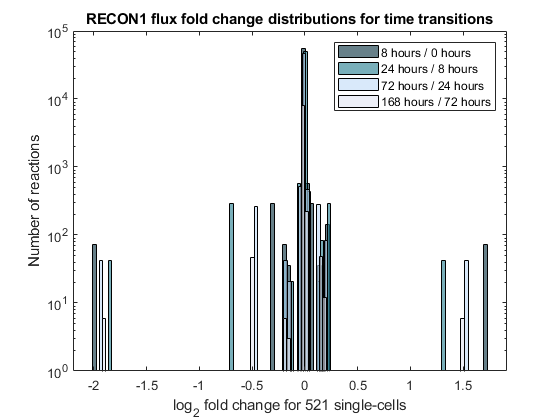

figure;
h1 = histogram(df08, 100);
hold on;
h2 = histogram(df24, 100);
hold on;
h3 = histogram(df72, 100);
hold on;
h4 = histogram(df168, 100);

set(h1, 'facecolor', "#022B3A");
set(h2, 'facecolor', "#1F7A8C");
set(h3, 'facecolor', "#BFDBF7");
set(h4, 'facecolor', "#E1E5F2");

legend("8 hours / 0 hours", ...
       "24 hours / 8 hours", ...
       "72 hours / 24 hours", ...
       "168 hours / 72 hours");
set(gca, 'YScale', 'log')
title("RECON1 flux fold change distributions for time transitions");
xlabel("log_{2} fold change for 521 single-cells");
ylabel("Number of reactions");

#### vii. Compute average flux and standard deviation for single cells

**Average metabolic fluxes**

Create an average matrix for each time point

df08  = df(:, 1:sum(idx8h));
df24  = df(:, (sum(idx8h)+1):(sum(idx1d)+sum(idx8h)));
df72  = df(:, (sum(idx1d)+sum(idx8h)+1):sum(idx3d)+sum(idx1d)+sum(idx8h), :);
df168 = df(:, (sum(idx3d)+sum(idx1d)+sum(idx8h)+1):sum(idx7d)+sum(idx3d)+sum(idx1d)+sum(idx8h));

First, let's compute the average metabolic flux fold changes.

avg_df08  = mean(df08, 2);
avg_df24  = mean(df24, 2);
avg_df72  = mean(df72, 2);
avg_df168 = mean(df168, 2);

We'll make a single matrix and take the sume of averages across all time points.

% Construct a single matrix of the average metabolic flux fold changes
avg_df = [avg_df08, avg_df24, avg_df72, avg_df168];

% Get the sum of averages across all time points
avg_overall = sum(avg_df, 2)/4;

Let's plot a histogram of the data distribution.

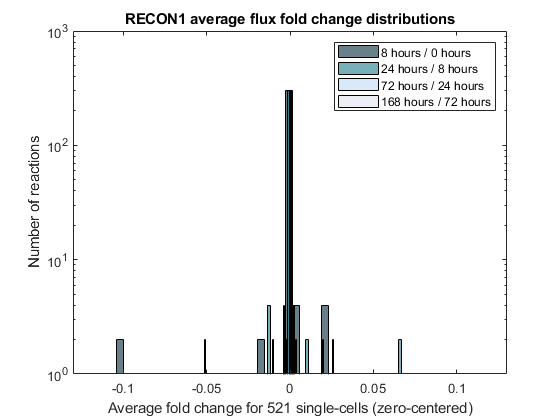

figure;
h1 = histogram(avg_df(:, 1)-1, 100);
hold on;
h2 = histogram(avg_df(:, 2)-1, 100);
hold on;
h3 = histogram(avg_df(:, 3)-1, 100);
hold on;
h4 = histogram(avg_df(:, 4)-1, 100);

set(h1, 'facecolor', "#022B3A");
set(h2, 'facecolor', "#1F7A8C");
set(h3, 'facecolor', "#BFDBF7");
set(h4, 'facecolor', "#E1E5F2");

legend("8 hours / 0 hours", ...
       "24 hours / 8 hours", ...
       "72 hours / 24 hours", ...
       "168 hours / 72 hours");
set(gca, 'YScale', 'log')
title("RECON1 average flux fold change distributions");
xlabel("Average fold change for 521 single-cells (zero-centered)");
ylabel("Number of reactions");
xlim([-0.13, 0.13])

**Standard deviation of metabolic fluxes**

% Compute variance of metabolic flux fold changes
var_df08  = var(df08, [], 2);
var_df24  = var(df24, [], 2);
var_df72  = var(df72, [], 2);
var_df168 = var(df168, [], 2);

We'll make a single matrix and take the sum of variances across all time points.

% Construct a single matrix of the variances
var_df = [var_df08, var_df24, var_df72, var_df168];

% Get the sum of variance across all time points
var_overall = sum(var_df, 2)/4;

Let's plot a histogram of the data distribution.

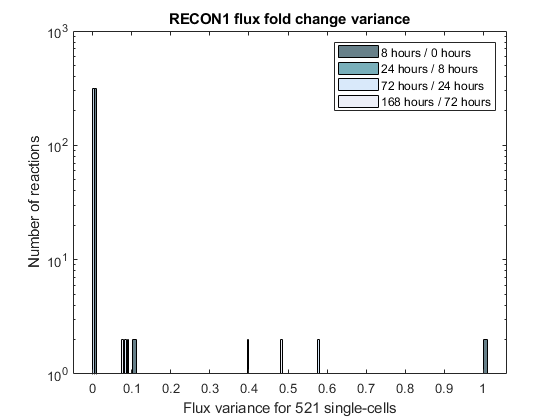

figure;
h1 = histogram(var_df(:, 1), 100);
hold on;
h2 = histogram(var_df(:, 2), 100);
hold on;
h3 = histogram(var_df(:, 3), 100);
hold on;
h4 = histogram(var_df(:, 4), 100);

set(h1, 'facecolor', "#022B3A");
set(h2, 'facecolor', "#1F7A8C");
set(h3, 'facecolor', "#BFDBF7");
set(h4, 'facecolor', "#E1E5F2");

legend("8 hours / 0 hours", ...
       "24 hours / 8 hours", ...
       "72 hours / 24 hours", ...
       "168 hours / 72 hours");
set(gca, 'YScale', 'log')
title("RECON1 flux fold change variance");
xlabel("Flux variance for 521 single-cells");
ylabel("Number of reactions");

%xlim([-0.3, 0.3])

**Sort the reactions by overall averages**

% Sort by descending
[~, idx] = sort(avg_overall, 'descend');
avg_ids = string(rxn_ids);
avg_ids = avg_ids(idx, :);

% Apply descend to matrix
final_df = avg_df(idx, :)-1;

**We need to make a string out of the data.**

tmp = [avg_df(:, 1)-1,  var_df(:, 1), ...
       avg_df(:, 2)-1,  var_df(:, 2), ...
       avg_df(:, 3)-1,  var_df(:, 3), ...
       avg_df(:, 4)-1,  var_df(:, 4), ...
       avg_overall-1, var_overall];
tmp = string(tmp);
tmp = tmp(idx, :);

**Now concatenate all of the data**

final_df = [avg_ids, tmp];
%final_df = final_df(idx, :);
final_df = ["ID", "Name", "Subsystem", ...
            "Mean(8/0)", "Var(8/0)", ...
            "Mean(24/8)", "Var(24/8)", ...
            "Mean(72/0)", "Var(72/24)", ...
            "Mean(168/0)", "Var(168/72)", ...
            "Total mean", "Total var"; ...
            final_df];

I am trying to test the hypothesis that the fold change for reaction r between time x and time 0 is significant compared to the average of that distribution. I did this using the Robust-zscore method.

tmp = avg_df(idx, :);
zscore = zeros(size(tmp));
pvalue = zeros(size(tmp));
for i = 1:size(tmp, 1)
    for j = 1:size(tmp, 2)
        zscore(i, j) = (tmp(i, j) - median(tmp, 'all')) / (1.4826*mad(tmp, [], 'all'));
        pvalue(i, j) = normpdf(zscore(i, j));
    end
end

final_zscore = ["ID", "Name", "Subsystem", ...
                "Z(8/0)", ...
                "Z(24/8)", ...
                "Z(72/24)", ...
                "Z(168/72)"; ...
                avg_ids, zscore];

final_pvalue = ["ID", "Name", "Subsystem", ...
                "P(8/0)", ...
                "P(24/8)", ...
                "P(72/24)", ...
                "P(168/72)"; ...
                avg_ids, pvalue];

### D. Differential reaction sensitivity analysis

First, remove identifiers and return to numerical

tmprxnko = str2double(tmprxnko(2:end, 4:end));

Now let's separate flux distributions by time point.

grate0d  = tmprxnko(:, idx0d);
grate8h  = tmprxnko(:, idx8h);
grate1d  = tmprxnko(:, idx1d);
grate3d  = tmprxnko(:, idx3d);
grate7d  = tmprxnko(:, idx7d);

Now let's plot histograms

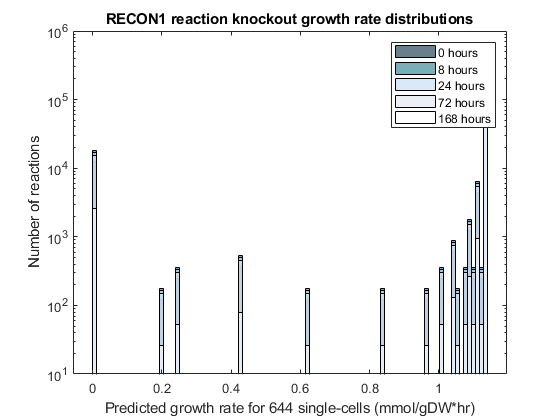

figure;
h1 = histogram(grate0d, 100);
hold on;
h2 = histogram(grate8h, 100);
hold on;
h3 = histogram(grate1d, 100);
hold on;
h4 = histogram(grate3d, 100);
hold on;
h5 = histogram(grate7d, 100);

set(h1, 'facecolor', "#022B3A");
set(h2, 'facecolor', "#1F7A8C");
set(h3, 'facecolor', "#BFDBF7");
set(h4, 'facecolor', "#E1E5F2");
set(h5, 'facecolor', "#FFFFFF");

legend("0 hours", ...
       "8 hours", ...
       "24 hours", ...
       "72 hours", ...
       "168 hours");
set(gca, 'YScale', 'log')
title("RECON1 reaction knockout growth rate distributions");
xlabel("Predicted growth rate for 644 single-cells (mmol/gDW*hr)");
ylabel("Number of reactions");

### E. Metabolic flux fold change comparing day t over day 0

#### i. Get fold change across different time points

I added a value of 1 to not run into infinite values.

fc0008  = (abs(grate8h)+1)  ./ mean(abs(grate0d)+1, 2);
fc0024  = (abs(grate1d)+1)  ./ mean(abs(grate0d)+1, 2);
fc0072  = (abs(grate3d)+1)  ./ mean(abs(grate0d)+1, 2);
fc00168 = (abs(grate7d)+1)  ./ mean(abs(grate0d)+1, 2);

#### iii. Concatenate vertically

df = [fc0008, fc0024, fc0072, fc00168];

#### iv. Remove reactions that have no fold change in any reaction 

keep_idx   = all(df-1, 2);
df         = df(keep_idx, :);
rxn_ids    = [model.rxns, model.rxnNames, model.subSystems];
rxn_ids    = rxn_ids(keep_idx, :);

#### v. Let's also apply the log2 operator on the data

log2df = log2(df);
df08   = log2df(:, 1:sum(idx8h));
df24   = log2df(:, (sum(idx8h)+1):(sum(idx1d)+sum(idx8h)));
df72   = log2df(:, (sum(idx1d)+sum(idx8h)+1):sum(idx3d)+sum(idx1d)+sum(idx8h), :);
df168  = log2df(:, (sum(idx3d)+sum(idx1d)+sum(idx8h)+1):sum(idx7d)+sum(idx3d)+sum(idx1d)+sum(idx8h));

#### vi. Let's plot a histogram of the data distribution

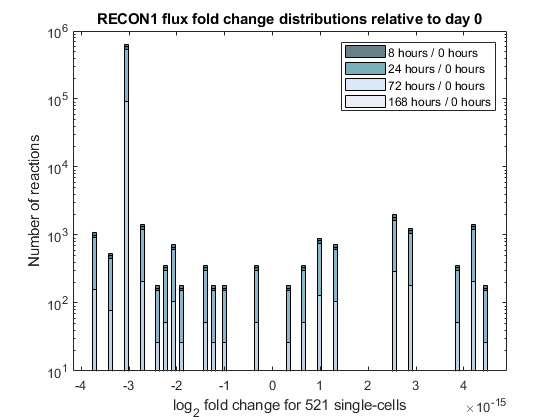

figure;
h1 = histogram(df08, 100);
hold on;
h2 = histogram(df24, 100);
hold on;
h3 = histogram(df72, 100);
hold on;
h4 = histogram(df168, 100);

set(h1, 'facecolor', "#022B3A");
set(h2, 'facecolor', "#1F7A8C");
set(h3, 'facecolor', "#BFDBF7");
set(h4, 'facecolor', "#E1E5F2");

legend("8 hours / 0 hours", ...
       "24 hours / 0 hours", ...
       "72 hours / 0 hours", ...
       "168 hours / 0 hours");
set(gca, 'YScale', 'log')
title("RECON1 flux fold change distributions relative to day 0");
xlabel("log_{2} fold change for 521 single-cells");
ylabel("Number of reactions");

#### vii. Compute average flux and standard deviation for single cells

**Average metabolic fluxes**

Create an average matrix for each time point

df08  = df(:, 1:sum(idx8h));
df24  = df(:, (sum(idx8h)+1):(sum(idx1d)+sum(idx8h)));
df72  = df(:, (sum(idx1d)+sum(idx8h)+1):sum(idx3d)+sum(idx1d)+sum(idx8h), :);
df168 = df(:, (sum(idx3d)+sum(idx1d)+sum(idx8h)+1):sum(idx7d)+sum(idx3d)+sum(idx1d)+sum(idx8h));

First, let's compute the average metabolic flux fold changes.

avg_df08 = mean(df08, 2);
avg_df24 = mean(df24, 2);
avg_df72 = mean(df72, 2);
avg_df168 = mean(df168, 2);

We'll make a single matrix and take the sume of averages across all time points.

% Construct a single matrix of the average metabolic flux fold changes
avg_df = [avg_df08, avg_df24, avg_df72, avg_df168];

% Get the sum of averages across all time points
avg_overall = sum(avg_df, 2)/4;

Let's plot a histogram of the data distribution.

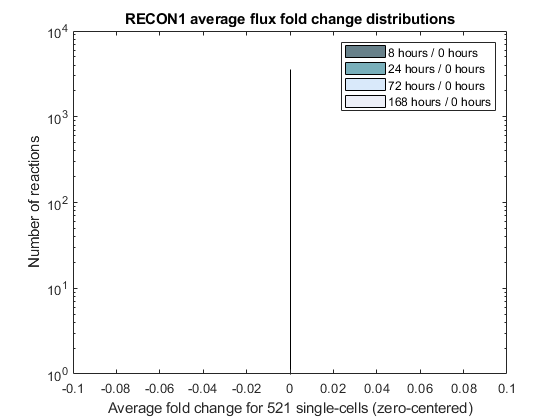

figure;
h1 = histogram(avg_df(:, 1)-1, 100);
hold on;
h2 = histogram(avg_df(:, 2)-1, 100);
hold on;
h3 = histogram(avg_df(:, 3)-1, 100);
hold on;
h4 = histogram(avg_df(:, 4)-1, 100);

set(h1, 'facecolor', "#022B3A");
set(h2, 'facecolor', "#1F7A8C");
set(h3, 'facecolor', "#BFDBF7");
set(h4, 'facecolor', "#E1E5F2");

legend("8 hours / 0 hours", ...
       "24 hours / 0 hours", ...
       "72 hours / 0 hours", ...
       "168 hours / 0 hours");
set(gca, 'YScale', 'log')
title("RECON1 average flux fold change distributions");
xlabel("Average fold change for 521 single-cells (zero-centered)");
ylabel("Number of reactions");
xlim([-0.1, 0.1])

**Standard deviation of metabolic fluxes**

% Compute variance of metabolic flux fold changes
var_df08  = var(df08, [], 2);
var_df24  = var(df24, [], 2);
var_df72  = var(df72, [], 2);
var_df168 = var(df168, [], 2);

We'll make a single matrix and take the sum of variances across all time points.

% Construct a single matrix of the variances
var_df = [var_df08, var_df24, var_df72, var_df168];

% Get the sum of variance across all time points
var_overall = sum(var_df, 2)/4;

Let's plot a histogram of the data distribution.

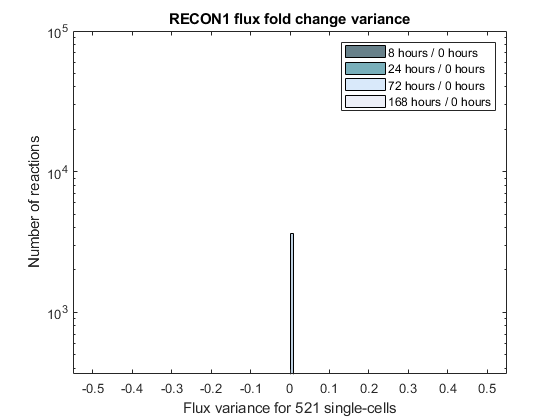

figure;
h1 = histogram(var_df(:, 1), 100);
hold on;
h2 = histogram(var_df(:, 2), 100);
hold on;
h3 = histogram(var_df(:, 3), 100);
hold on;
h4 = histogram(var_df(:, 4), 100);

set(h1, 'facecolor', "#022B3A");
set(h2, 'facecolor', "#1F7A8C");
set(h3, 'facecolor', "#BFDBF7");
set(h4, 'facecolor', "#E1E5F2");

legend("8 hours / 0 hours", ...
       "24 hours / 0 hours", ...
       "72 hours / 0 hours", ...
       "168 hours / 0 hours");
set(gca, 'YScale', 'log')
title("RECON1 flux fold change variance");
xlabel("Flux variance for 521 single-cells");
ylabel("Number of reactions");

%xlim([-0.3, 0.3])

**Sort the reactions by overall averages**

% Sort by descending
[~, idx] = sort(avg_overall, 'descend');
avg_ids = string(rxn_ids);
avg_ids = avg_ids(idx, :);

% Apply descend to matrix
final_df = avg_df(idx, :)-1;

**We need to make a string out of the data.**

tmp = [avg_df(:, 1)-1,  var_df(:, 1), ...
       avg_df(:, 2)-1,  var_df(:, 2), ...
       avg_df(:, 3)-1,  var_df(:, 3), ...
       avg_df(:, 4)-1,  var_df(:, 4), ...
       avg_overall-1, var_overall];
tmp = string(tmp);
tmp = tmp(idx, :);

**Now concatenate all of the data**

final_df = [avg_ids, tmp];
%final_df = final_df(idx, :);
final_df = ["ID", "Name", "Subsystem", ...
            "Mean(8/0)", "Var(8/0)", ...
            "Mean(24/0)", "Var(24/0)", ...
            "Mean(72/0)", "Var(72/0)", ...
            "Mean(168/0)", "Var(168/0)", ...
            "Total mean", "Total var"; ...
            final_df];

I am trying to test the hypothesis that the fold change for reaction r between time x and time 0 is significant compared to the average of that distribution. I did this using the Robust-zscore method.

tmp = avg_df(idx, :);
zscore = zeros(size(tmp));
pvalue = zeros(size(tmp));
for i = 1:size(tmp, 1)
    for j = 1:size(tmp, 2)
        zscore(i, j) = (tmp(i, j) - median(tmp, 'all')) / (1.4826*mad(tmp, [], 'all'));
        pvalue(i, j) = normpdf(zscore(i, j));
    end
end

Assemble the final dataset

final_zscore = ["ID", "Name", "Subsystem", ...
            "Z(8/0)", ...
            "Z(24/0)", ...
            "Z(72/0)", ...
            "Z(168/0)"; ...
            avg_ids, zscore];

final_pvalue = ["ID", "Name", "Subsystem", ...
            "P(8/0)", ...
            "P(24/0)", ...
            "P(72/0)", ...
            "P(168/0)"; ...
            avg_ids, pvalue];